# Visualisation Mars3D brut

clear; clc;

pc = 'Z:/'; % 'C:/Users/lehuen201/Nextcloud/'; % 
tsk = 'A_SDM_NEO/';
site = 'ES'; % 'ES' 'BDS' % % geog={'ES','Seine Estuary';'BDS','Bays of Seine';'BDV','Bay of Veys'};
wdpath = [pc 'Melting Pot/BDD/']; wdwork = [wdpath,tsk,'Matrices/'];
% wdworknc = [pc 'Melting Potes/' tsk 'ExtrNcdf/' site '/']; wdres = [wdpath,tsk,'Resultats/'];
wdworknc = ['E:/Copie-HD/' 'Melting Potes/' tsk 'ExtrNcdf/' site '/']; % Emplacement de sauvegarde des matrices generees
etudenc = [site,'_Ncf'];
anstr='2018';
leapyear=@(yr)~rem(yr,400)|rem(yr,100)&~rem(yr,4);
Var1D2D = load ([wdworknc,etudenc,'_Var1D2D_', anstr]);
Var1D2D_2017 = load ([wdworknc,etudenc,'_Var1D2D_', '2017']);

Visu H0

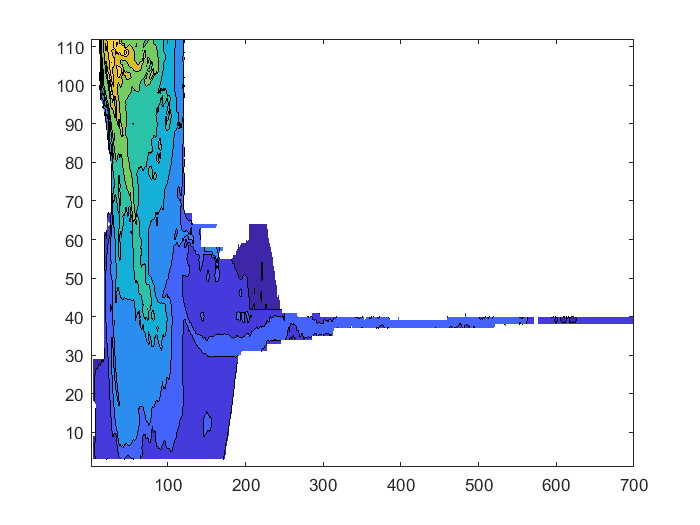

[NI,NJ]=meshgrid(Var1D2D.ni_full,Var1D2D.nj_full);
h0 = eval(['Var1D2D.h0_' anstr ';']);
lon = eval(['Var1D2D.lon_nc_' anstr ';']); lon(isnan(h0))=NaN;
lat = eval(['Var1D2D.lat_nc_' anstr ';']); lat(isnan(h0))=NaN;

contourf(NI,NJ,h0) % Version num de maille

% mesh(lon,lat,h0) % version SIG
% colorbar
% titreG = sprintf('%s - %s\nMean Oct 2018', Var1D2D.Varnames_hyd{25,1},Var1D2D.Varnames_hyd{25,2});
% title(titreG,'FontSize',8,'FontWeight','bold');

Définition du cadre zoom

h0_2017 = eval(['Var1D2D.h0_' '2017' ';']);

iminid=[0,0];imaxid=[699,190]; ishift=[0,111]; % col1 FULL, col2 ZOOM
jminid=[0,0]; jmaxid=[111,69]; jshift=[0,2];
site='ES';
if strcmp(site,'ES')
    iminid(1)=ishift(2); imaxid=iminid+109; % iminid(fz)=[ishift,0];imaxid(fz)=[220,109];
    jminid(1)=jshift(2); jmaxid=jminid+69; % jminid(fz)=[jshift,0]; jmaxid(fz)=[71,69];
end
range_i = imaxid-iminid+1; range_j = jmaxid-jminid+1;
fz=2; % 1 pour full, 2 pour zoom
contourf(lon,lat,h0(jminid(fz)+1:jmaxid(fz)+1,iminid(fz)+1:imaxid(fz)+1)) % version SIG


### Calcul var

Var3D = load ([wdworknc,etudenc,'_Var3D_',anstr]);
Var3D = Var3D.Var3D;

try xe = eval(['Var3D.' 'Hyd_XE' ';']);
catch xe = eval(['Var3D.' 'Hyd_XE' '_' anstr ';']);
end
p = 2*24; % definition du pas pour une journee 24h enregistrement toutes les 30 minutes

try eptot = eval(['Var3D.' 'Sed_EPTOT' ';']);
catch eptot = eval(['Var3D.' 'Sed_EPTOT' '_' anstr ';']);
end

% _Hyd_SAL_ _Hyd_TEMP_ _Hyd_UZ_ _Hyd_VZ_ _MES_mud_ _Sed_DZS_
sal = load ([wdworknc,etudenc,'_Hyd_SAL_',anstr]); 
vz = load ([wdworknc,etudenc,'_Hyd_VZ_',anstr]); 
dzs = load ([wdworknc,etudenc,'_Sed_DZS_',anstr]); 

% pour les 4D hyd=1:3 sed=1:4
% tmp3 = median(var(:,:,1:3,:),3,'omitnan'); tmp3 = permute(tmp3, [2 1 4 3]);
% pour tous
% tmp3 = median(var,3,'omitnan');
gap = 0.011;
HWater = h0-eptot+xe-gap; % h0 + xe
IfWater = h0-eptot+xe>gap;% 
Inont = sum(IfWater,3,'omitnan')/size(xe,3); % logical median not working : median(tmp3,3,'omitnan'); % 
IfEmer = h0-eptot+xe<gap; %IfEmer(isnan(h0))=NaN; % 
Emert = sum(IfEmer,3)/size(xe,3); % logical median not working : median(tmp3,3,'omitnan'); % 

### Vue spatiale

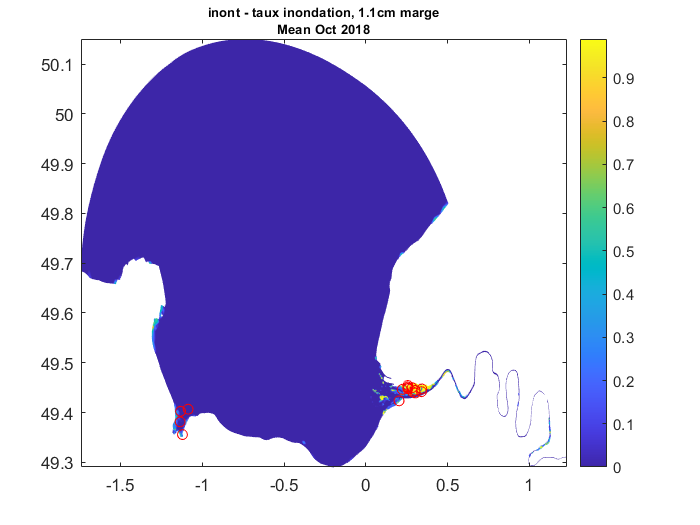

z = median(Emert,3,'omitnan'); % Emert; median(xe,3,'omitnan'); median(eptot,3,'omitnan'); 
titreG = sprintf('%s - %s\nMean Oct 2018', 'Emert','Emertion rate, gap 1.1cm');
rgvar = [min(z,[],'all','omitnan') max(z,[],'all','omitnan')];
% contourf(NI,NJ,z,100, 'LineColor','flat')
contourf(lon,lat,z,100, 'LineColor','flat')
colorbar
title(titreG,'FontSize',8,'FontWeight','bold');
hold on
indices=[190,51; %delta 0.01 terre 62,210
        184,21;
        200,54; 200,55; 200,57; 200,59;%zarbos  
        207,48; 207,57; 
        211,51; 211,44; %nawak % bout de filandre ok
        220,44; 221,54;
        27,10; 20,20; 15,15; %bdv subtidal
        5,3];
for i = 1:length(indices)
    indices(i,3)=lon(indices(i,2),indices(i,1));
    indices(i,4)=lat(indices(i,2),indices(i,1));
end
plot(indices(:,3),indices(:,4),'ro','markersize', 6)
hold off

### Vue temporelle

ans =     'NINJ 190-51,
     long : 0.222738; lat : 49.446534'


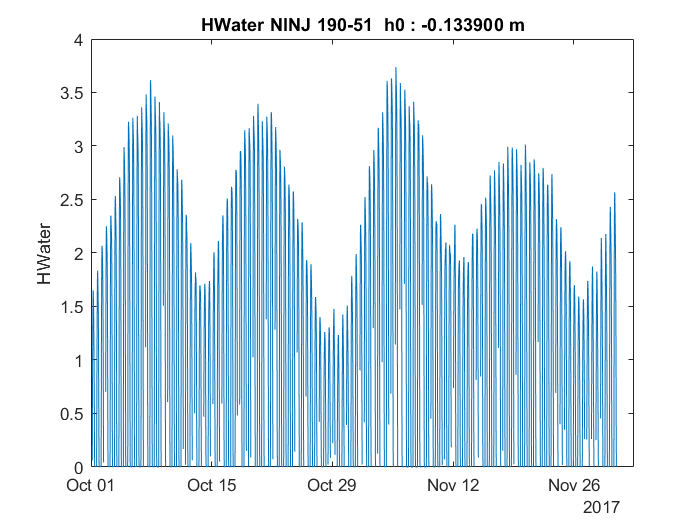

ans =     'NINJ 184-21,
     long : 0.203606; lat : 49.423537'


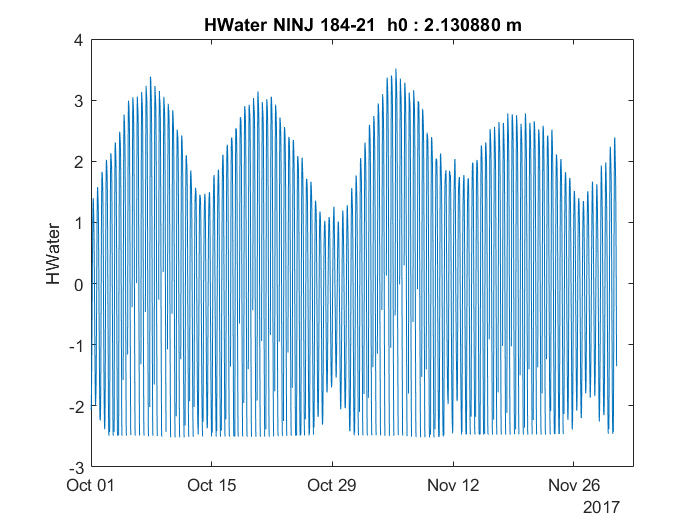

ans =     'NINJ 200-54,
     long : 0.257080; lat : 49.447766'


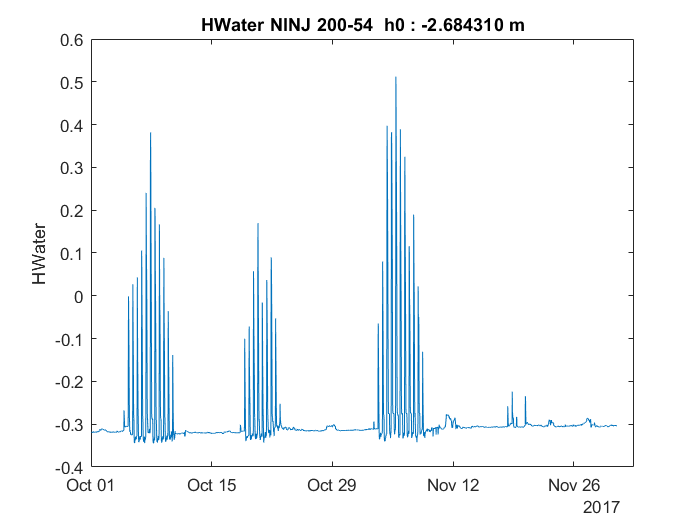

ans =     'NINJ 200-55,
     long : 0.257010; lat : 49.448707'


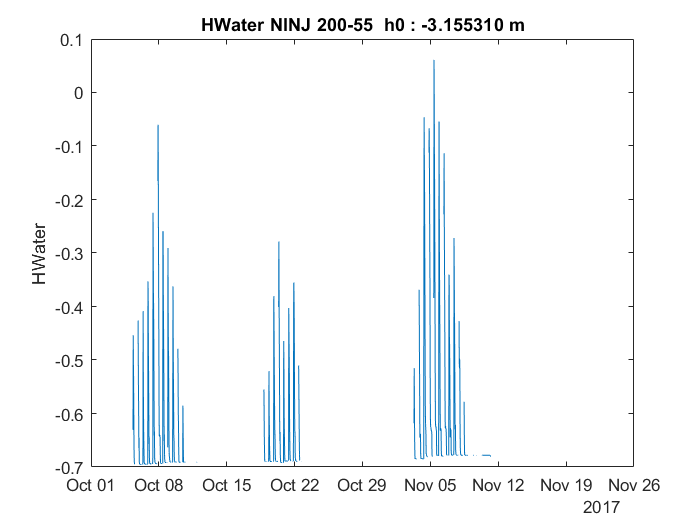

ans =     'NINJ 200-57,
     long : 0.256916; lat : 49.451136'


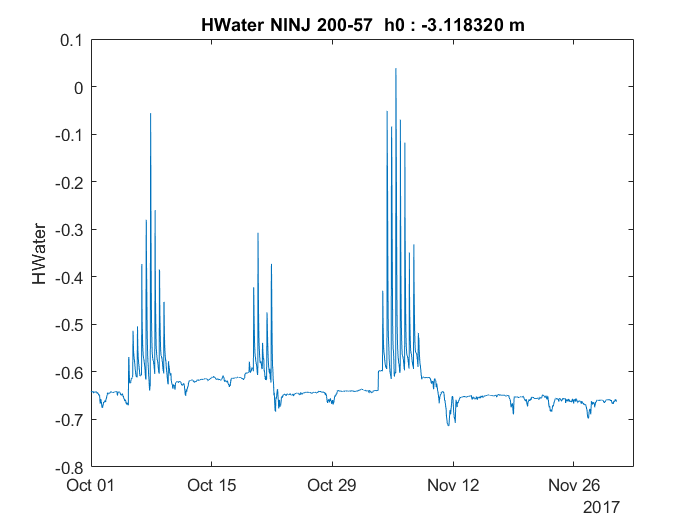

ans =     'NINJ 200-59,
     long : 0.257112; lat : 49.454338'


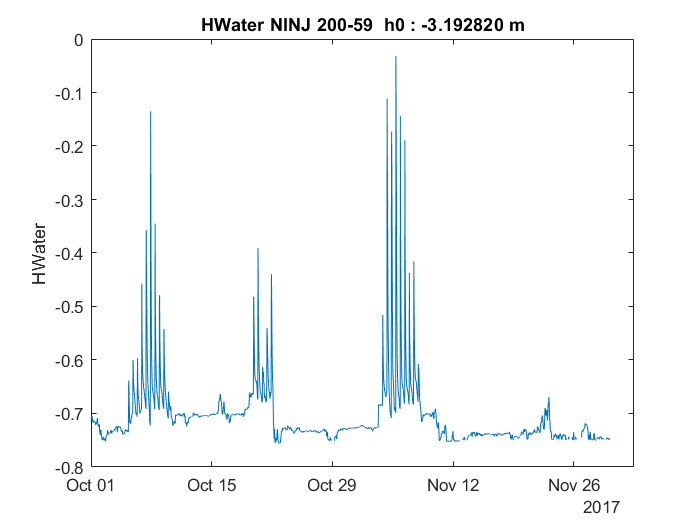

ans =     'NINJ 207-48,
     long : 0.285781; lat : 49.441879'


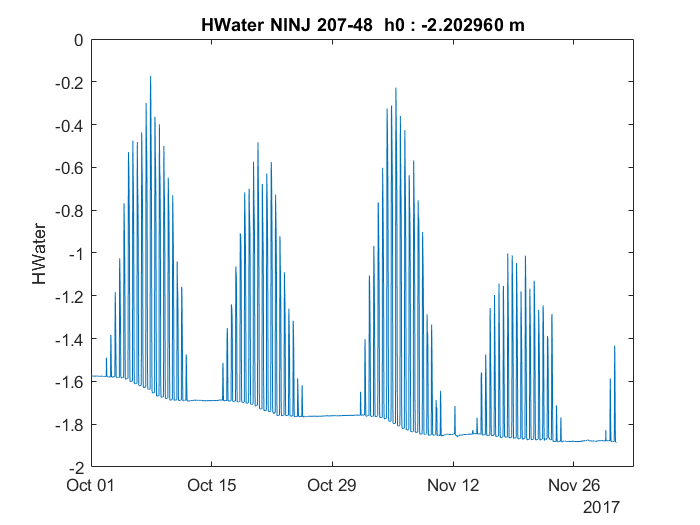

ans =     'NINJ 207-57,
     long : 0.283759; lat : 49.449860'


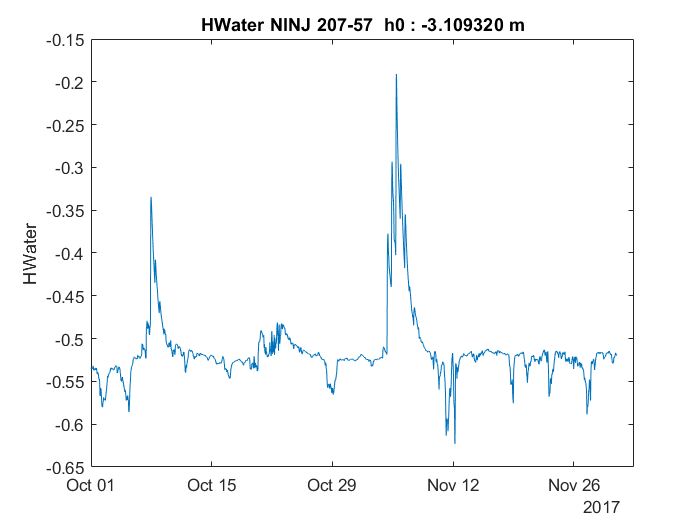

ans =     'NINJ 211-51,
     long : 0.301461; lat : 49.444469'


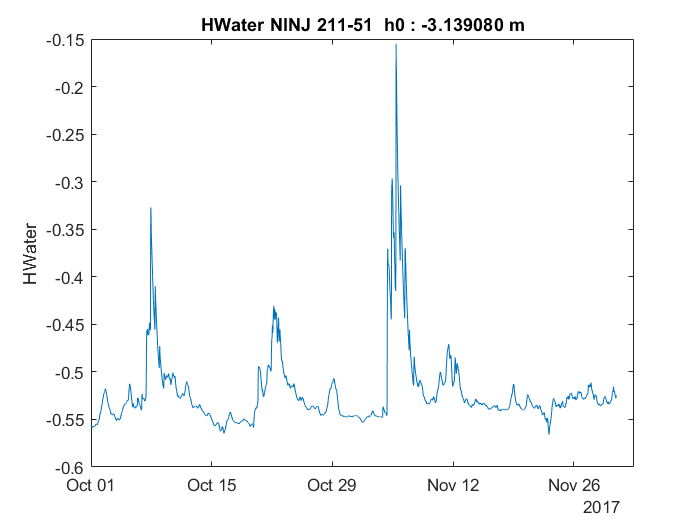

ans =     'NINJ 211-44,
     long : 0.303233; lat : 49.439285'


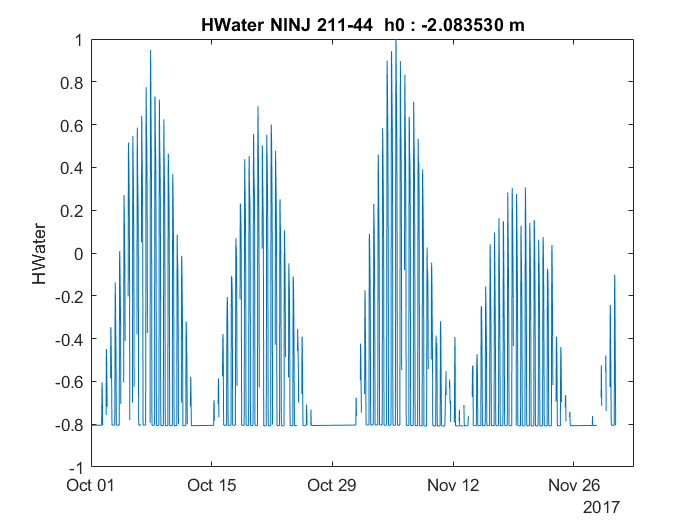

ans =     'NINJ 220-44,
     long : 0.340559; lat : 49.442037'


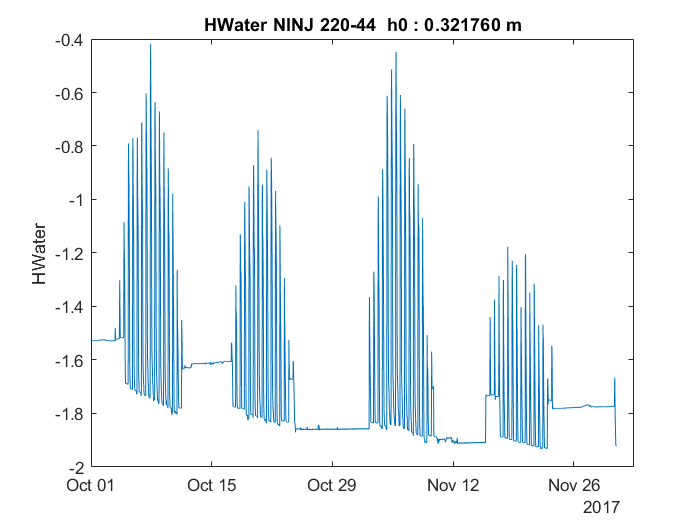

ans =     'NINJ 221-54,
     long : 0.342699; lat : 49.447419'


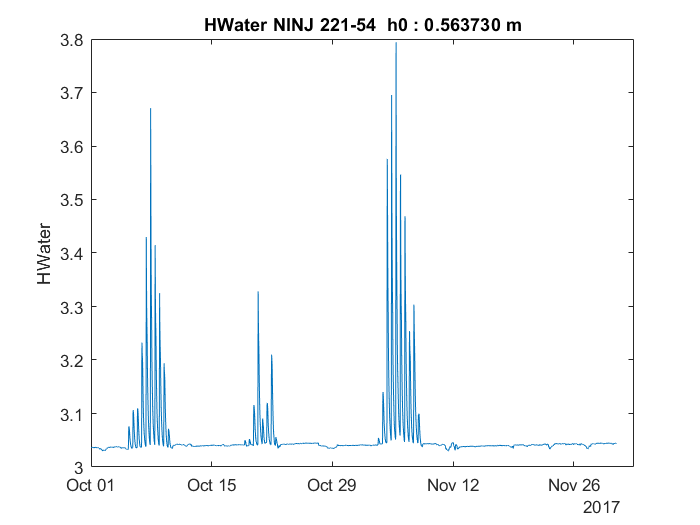

ans =     'NINJ 27-10,
     long : -1.086062; lat : 49.406782'


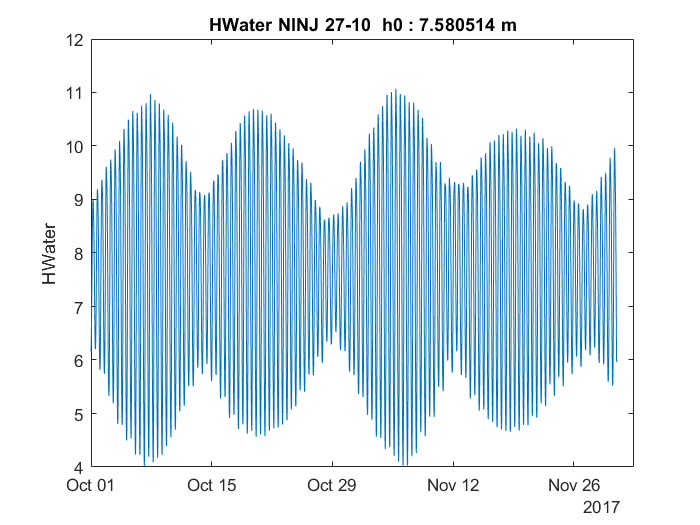

ans =     'NINJ 20-20,
     long : -1.132673; lat : 49.402493'


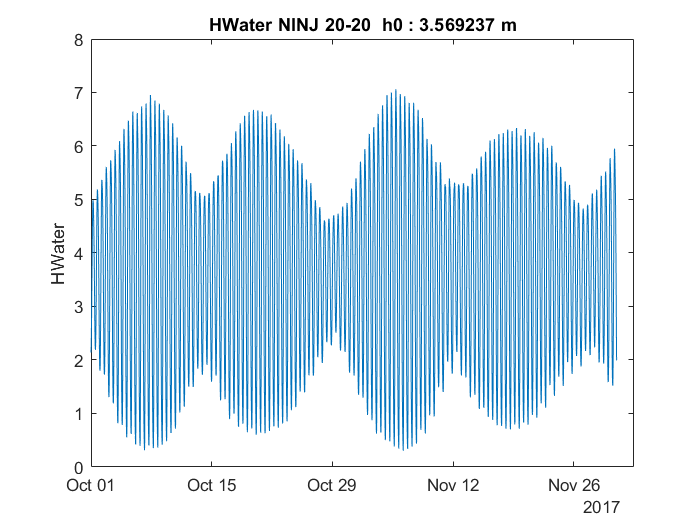

ans =     'NINJ 15-15,
     long : -1.134926; lat : 49.381400'


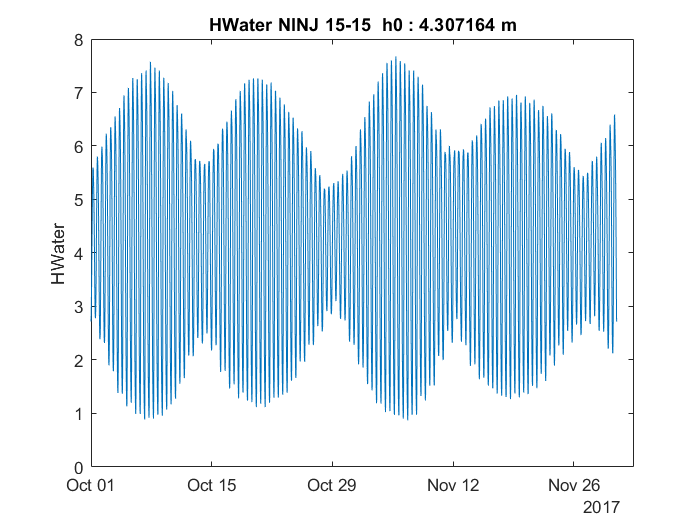

ans =     'NINJ 5-3,
     long : -1.120751; lat : 49.355759'


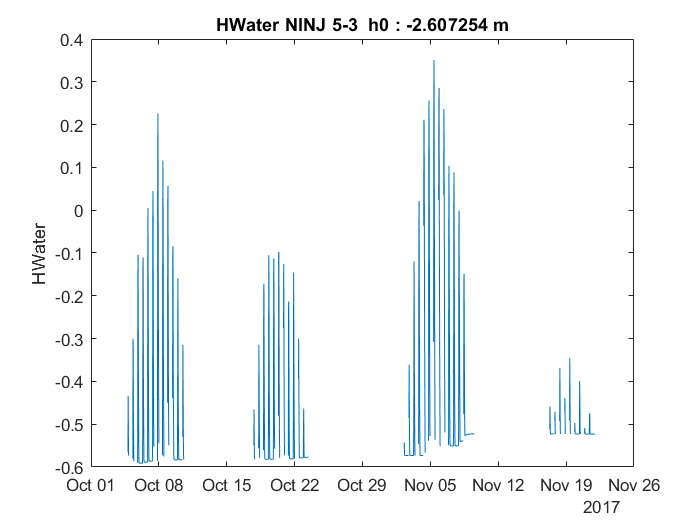

timelong=2*1464;%4320; %1464 : 1 mois
for i = 1:length(indices)
    figure;clf;
    sprintf('NINJ %d-%d,\nlong : %f; lat : %f',indices(i,1),indices(i,2),indices(i,3),indices(i,4))
    titreG=sprintf('NINJ %d-%d  h0 : %f m',indices(i,1),indices(i,2),h0(indices(i,2),indices(i,1)));
    tmp = HWater(indices(i,2),indices(i,1),1:timelong); tmp = permute(tmp,[3,1,2]);
    plot(Var1D2D.TIMEdt_2018(1:timelong),tmp); title(['HWater ' titreG]);
    ylabel('HWater');
%     tmp = IfWater(indices(i,2),indices(i,1),1:timelong); tmp = permute(tmp,[3,1,2]);
%     plot(Var1D2D.TIMEdt_2018(1:timelong),tmp); title(['IfWater ' titreG]);
%     ylabel('IfWater');
%     tmp = IfEmer(indices(i,2),indices(i,1),1:timelong); tmp = permute(tmp,[3,1,2]);
%     plot(Var1D2D.TIMEdt_2018(1:timelong),tmp); title(['IfWater ' titreG]);
%     ylabel('IfEmer');
end

### Distribution

% tmp = Inont;
% finesse = 100;
% histogram(tmp,finesse,'EdgeColor','none','Normalization','probability');
% title(sprintf('%s - %s\nMean Oct 2018', Var1D2D.Varnames_hyd{varid,1},Var1D2D.Varnames_hyd{varid,2}));
% ylabel('Normalized Density');

### Calcul Mortes/Vives eaux

tmp = HWater;
nearZero = @(x,tol) x.*(abs(x)>=tol.*1); tol = 0.001; % nearZero = @(x,tol) abs(x)<=tol;
MHVE = nearZero(max(max(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan'),[],4,'omitnan'),tol);
MHME = nearZero(min(max(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan'),[],4,'omitnan'),tol);
MBME = nearZero(max(min(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan'),[],4,'omitnan'),tol);
MBVE = nearZero(min(min(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan'),[],4,'omitnan'),tol);

ampl_d = max(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan')- ...
        min(reshape(tmp(:,:,1:floor(size(tmp,3)/p)*p),size(tmp,1),size(tmp,2),p,[]),[],3,'omitnan');
ampl_d = permute(ampl_d,[1 2 4 3]);
ampl_m = mean(ampl_d,3,"omitnan");

### Vue temporelle

for i = 1:length(indices)
    sprintf('NINJ %d-%d long : %f; lat : %f,\n h0 : %f m',indices(i,1),indices(i,2),indices(i,3),indices(i,4),h0(indices(i,2),indices(i,1)))
    tmp = ampl_d(indices(i,2),indices(i,1),:); tmp = permute(tmp,[3,1,2]);
    figure;clf;
    plot(tmp); title('ampl');
end

### Vue Spatiale

% contourf(lon,lat,MHVE,100, 'LineColor','flat')
% colorbar
% titreG = sprintf('%s - %s\nMean Oct 2018', 'MHVE','');
% title(titreG,'FontSize',8,'FontWeight','bold');
% 
% contourf(lon,lat,MHME,100, 'LineColor','flat')
% colorbar
% titreG = sprintf('%s - %s\nMean Oct 2018', 'MHME','');
% title(titreG,'FontSize',8,'FontWeight','bold');
% 
% contourf(lon,lat,MBME,100, 'LineColor','flat')
% colorbar
% titreG = sprintf('%s - %s\nMean Oct 2018', 'MBME','');
% title(titreG,'FontSize',8,'FontWeight','bold');
% 
% contourf(lon,lat,MBVE,100, 'LineColor','flat')
% colorbar
% titreG = sprintf('%s - %s\nMean Oct 2018', 'MBVE','');
% title(titreG,'FontSize',8,'FontWeight','bold');

# Cartes

### Definition des bornes spatiales d'intéret

% boxfrmetro = [-4.87, 42.33; 8.23, 51.14]; % Selon LambII EPSG 27572 % xfrmetro=[-9.86,10.38]; yfrmetro=[41.15,51.56] % Coord selon L93 EPSG 2154
% boxnormlon = [-2, 0.8]; boxnormlat = [49, 49.7]; boxnorm = [-2, 49 ; 0.8, 49.7];
% boxbdslon = [-0.1, 0.45]; boxbdslat = [49.3, 49.7];
% boxestlon = [0.1, 0.2]; boxestlat = [49.35, 49.55];

### Decoupage de l'emprise

% varid = 25; Var1D2D.Varnames_hyd{varid,5} % 
% try var2 = eval([Var1D2D.Varnames_hyd{varid,5} ';']);
% catch var2 = eval([Var1D2D.Varnames_hyd{varid,5} '_' anstr ';']);
% end
% lon = eval(['Var1D2D.lon_nc_' anstr ';']);
% lat = eval(['Var1D2D.lat_nc_' anstr ';']);
% tmp = var2;
% box_lon = [-0.01 0.39]; 
% box_lat = [49.35 49.55];
% 
% % iminid_hyd = 0 ; imaxid_hyd = 699 ; jminid_hyd = 0 ; jmaxid_hyd = 111 ;
% % iminid_sed = 0 ; imaxid_sed = 699 ; jminid_sed = 0 ; jmaxid_sed = 111 ;
% % hyd_i = imaxid_hyd-iminid_hyd+1; hyd_j = jmaxid_hyd-jminid_hyd+1;
% % sed_i = imaxid_sed-iminid_sed+1; sed_j = jmaxid_sed-jminid_sed+1;
% 
% [~,tp]=min(sqrt((lon - box_lon(1)).^2 + (lat - box_lat(1)).^2),[],'all','linear');
% [jminid_hyd,iminid_hyd] = ind2sub(size(lon),tp);
% [~,tp]=min(sqrt((lon - box_lon(2)).^2 + (lat - box_lat(2)).^2),[],'all','linear');
% [jmaxid_hyd,imaxid_hyd] = ind2sub(size(lat),tp);
% 
% lon = lon(jminid_hyd:jmaxid_hyd,iminid_hyd:imaxid_hyd);
% lat = lat(jminid_hyd:jmaxid_hyd,iminid_hyd:imaxid_hyd);
% z = tmp(jminid_hyd:jmaxid_hyd,iminid_hyd:imaxid_hyd);
% contourf(lon,lat,z,100, 'LineColor','flat')
% geoshow(lat,lon,z, 'DisplayType', 'surface');
% % mesh(x,y,z,'EdgeColor','interp','FaceAlpha',0.4) % 3D
% xlabel('Longitude','FontSize',8); ylabel('Latitude','FontSize',8);
% vartitle = sprintf('%s (%s) in %s \n%s', 'Bathymetry', 'm', anstr, 'Check emprise');
% title(vartitle,'FontSize',8,'FontWeight','bold');